% 生成一个随机输入序列
N = 8;
x = rand(1, N) + 1i * rand(1, N);

% 使用递归FFT
X_recursive = recursive_fft(x);

% 使用MATLAB内置的FFT函数
X_builtin = fft(x);

% 显示结果
disp('Input sequence:');

Input sequence:


disp(x);

  列 1
   0.3480 + 0.7360i
  列 2
   0.1217 + 0.7947i
  列 3
   0.8842 + 0.5449i
  列 4
   0.0943 + 0.6862i
  列 5
   0.9300 + 0.8936i
  列 6
   0.3990 + 0.0548i
  列 7
   0.0474 + 0.3037i
  列 8
   0.3424 + 0.0462i



disp('FFT result (recursive):');

FFT result (recursive):


disp(X_recursive);

  列 1
   3.1669 + 4.0601i
  列 2
   0.6143 - 0.5523i
  列 3
   0.4636 + 0.6970i
  列 4
   0.1732 + 0.9800i
  列 5
   1.2523 + 0.8963i
  列 6
  -1.2958 - 1.4366i
  列 7
   0.2294 + 0.8651i
  列 8
  -1.8197 + 0.3781i



disp('FFT result (builtin):');

FFT result (builtin):


disp(X_builtin);

  列 1
   3.1669 + 4.0601i
  列 2
   0.6143 - 0.5523i
  列 3
   0.4636 + 0.6970i
  列 4
   0.1732 + 0.9800i
  列 5
   1.2523 + 0.8963i
  列 6
  -1.2958 - 1.4366i
  列 7
   0.2294 + 0.8651i
  列 8
  -1.8197 + 0.3781i



% 比较结果
disp('Comparison:');

Comparison:


disp('Max absolute difference:');

Max absolute difference:


disp(max(abs(X_recursive - X_builtin)));

   3.1402e-16


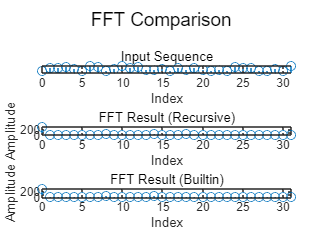

% 生成一个随机输入序列
N = 32;
x = rand(1, N)*15 + 1i * rand(1, N)*5;

% 使用递归FFT
X_recursive = recursive_fft(x);

% 使用MATLAB内置的FFT函数
X_builtin = fft(x);

% 绘制输入序列的幅度谱图
subplot(3, 1, 1);
stem(0:N-1, abs(x));
title('Input Sequence');
xlabel('Index');
ylabel('Amplitude');

% 绘制递归FFT结果的幅度谱图
subplot(3, 1, 2);
stem(0:N-1, abs(X_recursive));
title('FFT Result (Recursive)');
xlabel('Index');
ylabel('Amplitude');

% 绘制内置FFT结果的幅度谱图
subplot(3, 1, 3);
stem(0:N-1, abs(X_builtin));
title('FFT Result (Builtin)');
xlabel('Index');
ylabel('Amplitude');

% 显示图形
sgtitle('FFT Comparison');

% 生成一个随机输入序列
N = 8;
x = rand(1, N) + 1i * rand(1, N);

% 使用基2FFT计算FFT
X_iterative = iterative_fft(x);

Index exceeds the number of
array elements. Index must not
exceed 8.
出错 iterative_fft (第 22 行)
                odd = x(index + step);


% 显示结果
disp('Input sequence:');
disp(x);

disp('FFT result (iterative):');
disp(X_iterative);

